# **Gráfica del Espectro Elástico de la **

# **Norma Ecuatoriana de la Construcción (NEC)**

***Realizado por: Damián Mateo Villa Clavijo ***

## ***Resumen:***

El siguiente Script pretende evaluar los conocimientos adquiridos por el estudiante en el tema: Espectros Elásticos de Diseño Sismorresistente. En donde, mediante las ecuaciones presentadas en la normativa Ecuatoriana de la Construcción (NEC) los estudiantes deberán elaborar un código que replique los resultados presentados en este Script, para diferentes tipos de suelo y diferentes rangos de periodos. 

**Palabras Clave:** Ingeniería Civil, Estructuras Sismorresistentes, Espectros Elásticos, Diseño Estructural.

## **Objetivos de Aprendizaje**

*a, Implementar las ecuaciones presentadas en la normativas ecuatoriana de la construcción (NEC) para la elaboración de espectros elásticos.*

*b. Elaborar un código que permita al usuario seleccionar el espectro para un tipo de suelo diferente*

*c. Elaborar un código que permita al usuario seleccionar el rango del periodo que desea implementar en el espectro.*

## **Conceptos Fundamentales**

*El espectro a elaborar se configura como se muestra en la siguiente imagen. (Tomado de: NEC - SE - DS Capítulo 3).*

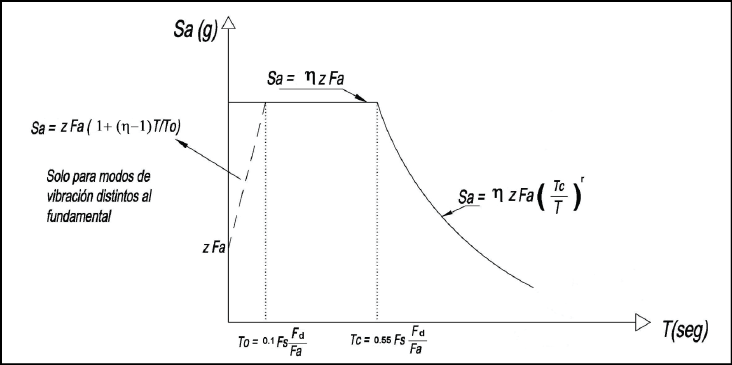

Donde:

**n** = Razón entrela aceleración espectral Sa(T = 0.1 s) y el PGA para el períodode retorno seleccionado.

**Fa** = Coeficiente de amplificación de suelo en la zonade períodocortó. Amplifica las ordenadas del espectro elástico de respuesta de aceleraciones para diseño en roca, considerando los efectos de sitio.

**Fd** = Coeficiente de amplificación de suelo. Amplifica las ordenadas del espectro elástico de respuesta de desplazamientos para diseño en roca, considerando los efectos de sitio.

**Fs** = Coeficiente de amplificación de suelo. Considera el comportamiento no lineal de los suelos, la degradación del períododel sitio que depende de la intensidad y contenido de frecuencia de la excitación sísmica y los desplazamientos relativos del suelo, para los espectros de aceleraciones y desplazamientos.

**Sa** = Espectro de respuesta elástico de aceleraciones (expresado como fracción de la aceleración de la gravedad g). Depende del períodoo modo de vibración de la estructura.

**T** = Período fundamental de vibración de la estructura.

**T0** = Períodolímitede vibración en el espectro sísmico elástico de aceleraciones que representa el sismo de diseño.

**Tc** = Período límite de vibración en el espectro sísmico elástico de aceleraciones que representa el sismo de diseño.

**Z** = Aceleración máxima en roca esperada para elsismo de diseño, expresada como fracción de la aceleración de la gravedad g.

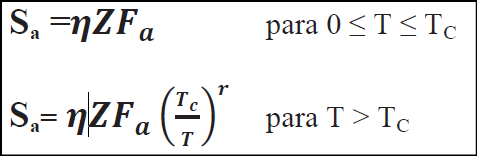

Donde:

**r** = Factor usado en el espectro de diseño elástico, cuyos valores dependen de la ubicación geográfica del proyecto. 

        **r** = 1 para todos los suelos, con excepción del suelo tipo E

        **r** = 1.5 para tipo de suelo E.

**n** = 1.8 para provincias de la Costa (Excepto Esmeraldas)

**n** = 2.48 para provincias de la Sierra, Esmeraldas y Galápagos.

**n** = 2.60 para provincias del Oriente.

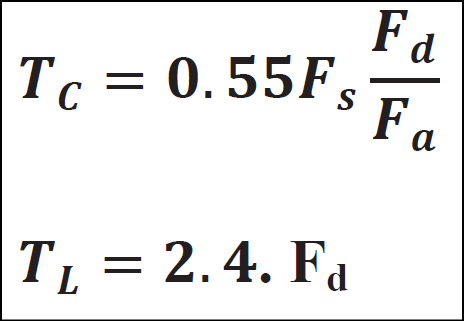

Los factores Fa, Fd y Fs se obtienen de las siguientes tablas:

**Fa**: Coeficiente de amplificación de suelo en la zona de período corto, tomando en cuenta los efectos de Sitio.

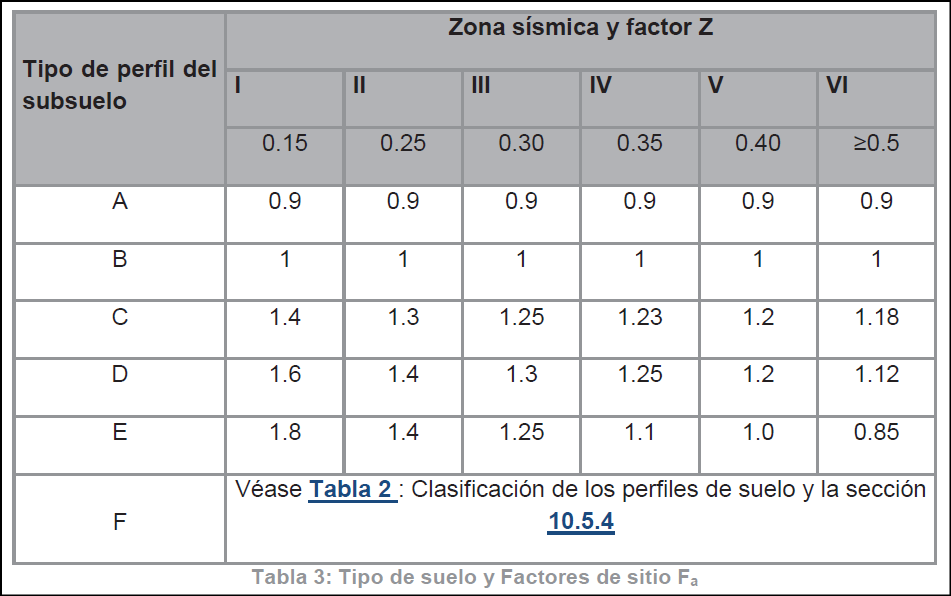

**Fd** = Amplificación de las ordenadas del espectro elástico de respuesta de desplazamientos para diseño en roca, tomando en cuenta los efectos de Sitio.

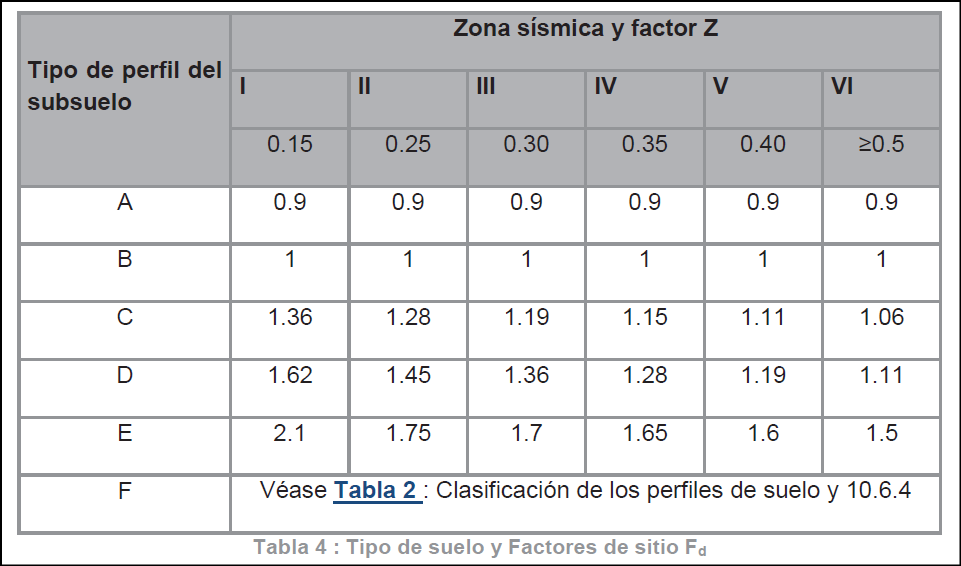

**Fs** = Comportamiento no lineal de los suelos, tomando en cuenta los efectos de Sitio.

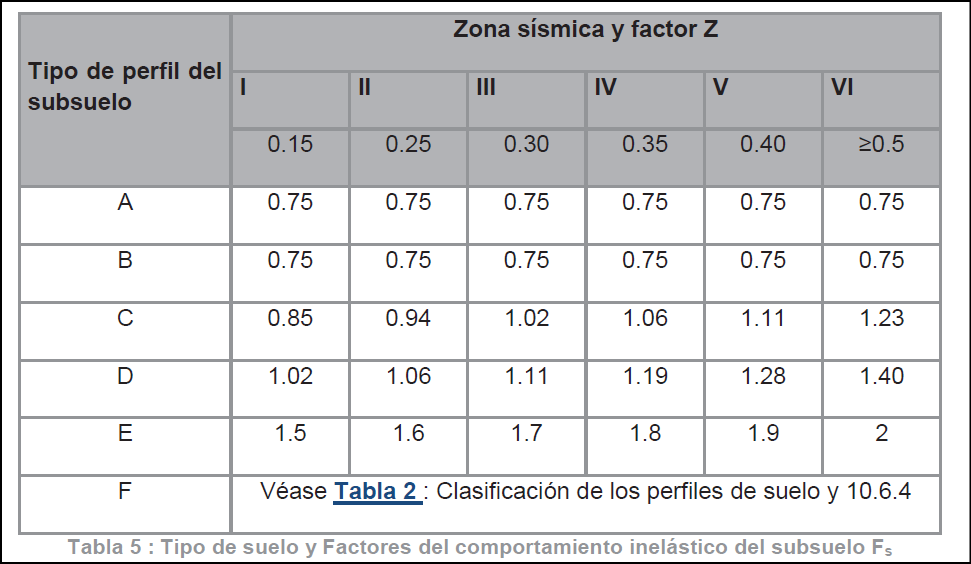

## **1.Definición de Variables**

n_vec = [1.80 2.48 2.60];                           % Razón entre la aceleración espectral (Sa) y el (PGA) para el periodo de retorno seleccionado
r_vec = [1 1 1 1.5 1.5];                            % Factor desarrollado en base al espectro elástico, cuyos valores dependen de la ubicación geográfica
z_vec = [0.15 0.25 0.3 0.35 0.4 0.5];               % Aceleración Máxima en roca esperada para el sismo de Diseño.
Fa_mat = [0.9 0.9 0.9 0.9 0.9 0.9 ; 1 1 1 1 1 1 ; 1.4 1.3 1.25 1.23 1.2 1.18 ;...
    1.6 1.4 1.3 1.25 1.2 1.12 ; 1.8 1.5 1.39 1.26 1.14 0.97]; 
                                                    % Matriz de coeficientes de amplificación de suelo en la zona de periodo corto
Fd_mat = [0.9 0.9 0.9 0.9 0.9 0.9 ; 1 1 1 1 1 1 ; 1.6 1.5 1.4 1.35 1.3 1.25 ;...
    1.9 1.7 1.6 1.5 1.4 1.3 ; 2.1 1.75 1.7 1.65 1.6 1.5]; 
                                                    % Matriz de coeficientes de desplazamientos para diseño en roca
Fs_mat = [0.75 0.75 0.75 0.75 0.75 0.75 ; 0.75 0.75 0.75 0.75 0.75 0.75 ;...
    1 1.1 1.2 1.25 1.3 1.45 ; 1.2 1.25 1.3 1.4 1.5 1.65 ; 1.5 1.6 1.7 1.8 1.9 2]; 
                                                    % Matriz de factor de comportamiento lineal de los suelos
tipos_suelo = char('A','B','C','D','E');
z_sismica = char('I','II','III','IV','V','VI');
g = 9.81;                                         
fig=1;                                              % inicio el contador de figuras



## **2.Ingreso de Variables**

% Seleccione la Zona Sísmica para Graficar los Espectros de Zona
% Según Normativa: (NEC-SE-DS)


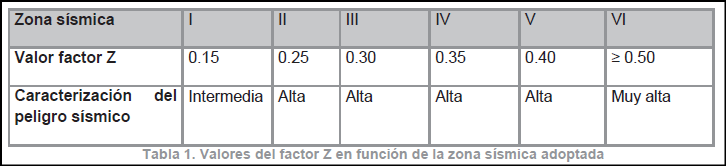


Variable2 = 4

Variable2 = 4

%Seleccione la Ubicación Geográfica de estudio:
% n=1 Para Provincias de la Costa (Excepto Esmeraldas)
% n=2 Para Provincias de la Sierra, Esmeraldas y Galápagos
% n=3 Para Provincias del Oriente

Variable3 = 1

Variable3 = 1

% Seleccione el Periodo (Segundos) de Vibracición de la Estructura:

Variable4 = 6

Variable4 = 6

## **3.Cálculo de Variables**

if Variable3 == 1                               % Determina el valor de n en base a la selección de Variable3
    n = 1.80;
else
        if Variable3 == 2
            n = 2.48;
        else
            n = 2.60;
        end
end

for i = 1:5
    Fa(i) = Fa_mat(i,Variable2);                % Factor Fa en base a la selección y la tabla 3 de la NEC-SE-DS
    Fd(i) = Fd_mat(i,Variable2);                % Factor Fd en base a la selección y la tabla 4 de la NEC-SE-DS
    Fs(i) = Fs_mat(i,Variable2);                % Factor Fs en base a la selección y la tabla 5 de la NEC-SE-DS
end

z = z_vec(Variable2);                           % Factor Z en base a la selección y la tabla 1 de la NEC-SE-DS

T = 0.01:0.01:Variable4;                        % Vector de Periodos en Segundos
Sa = zeros(5,length(T));                        % Vector que guarda memoria de T

for i = 1:5
    T0(i) = 0.1*Fs(i)*Fd(i)/Fa(i);              % calula el valor del periodo T0
    TC(i) = 0.55*Fs(i)*Fd(i)/Fa(i);             % calcula el valor del periodo TC
end



## **4.Posición de Variables en el Vector Periodos**

for j = 1: 5
    for i = 1:length(T)
        minimo1 (j,i) = abs(T0(j)-T(i));         % Vector de determina la diferencia de valores T0 y Periodos T
        minimo2 (j,i) = abs(TC(j)-T(i));         % Vector de determina la diferencia de valores TC y Periodos T
    end
end

    [valor1,idx1] = min(minimo1,[],2);           % Posición en T para T0
    [valor2,idx2] = min(minimo2,[],2);           % Posición en T para TC

    

## **5. Cálculo de Vector de Aceleraciones**

for j = 1:5
    for i = 1:idx1(j)
        Sa(j,i) = z*Fa(j)*(1+(n-1)*T(i)/T0(j)); 
    end
end

                                                   % 2.4.2 Vector de aceleraciones meseta ( T0 < T < TC)

for j = 1:5
    for i = idx1(j)+1:idx2(j)
        Sa(j,i) = n*z*Fa(j);
    end
end

                                                   % 2.4.3 Vector de aceleraciones meseta ( T0 < T < TC)

for j = 1:5
    for i = idx2(j)+1:length(T)
        Sa(j,i) = n*z*Fa(j)*((TC(j)/T(i))^r_vec(j));
    end
end


## **6. Gráfica Espectro para Zona Sísmica**

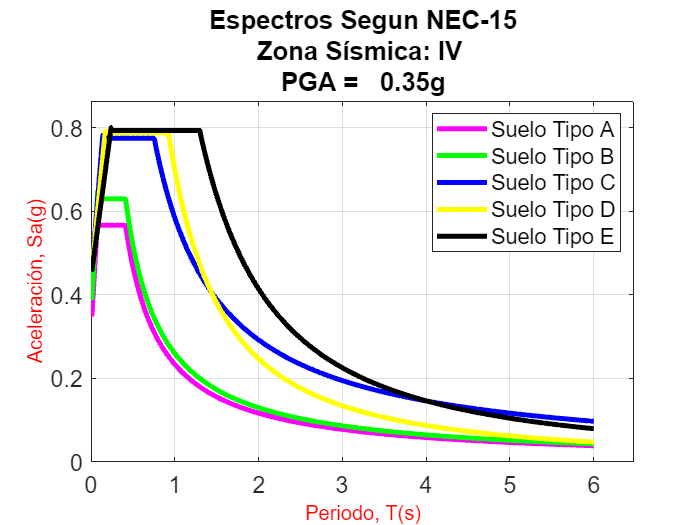

figure(fig)
fig=fig+1;
    plot(T,Sa(1,:),'m','Linewidth',3)
hold on
    plot(T,Sa(2,:),'g','Linewidth',3)
    plot(T,Sa(3,:),'b','Linewidth',3)
    plot(T,Sa(4,:),'y','Linewidth',3)
    plot(T,Sa(5,:),'k','Linewidth',3)
grid on
set(gca,'FontSize',14,'Fontname','Arial')
legend('Suelo Tipo A','Suelo Tipo B','Suelo Tipo C','Suelo Tipo D','Suelo Tipo E','FontSize',13)
title(sprintf('Espectros Segun NEC-15\nZona Sísmica: %s\nPGA = %6.2fg',z_sismica(Variable2,:),z))
xlabel('Periodo, T(s)','Color','r','FontSize',12)
ylabel('Aceleración, Sa(g)','Color','r','FontSize',12)
MaxSa = max(Sa,[],'all');
MaxT = max(T,[],'all');
ylim([0 MaxSa*1.08])
xlim([0 MaxT*1.08])
grid on
hold off

## 7. Bibliografía

Normativa Ecuatoriana de la Construcción disponible en:

[https://www.habitatyvivienda.gob.ec/documentos-normativos-nec-norma-ecuatoriana-de-la-construccion/](https://www.habitatyvivienda.gob.ec/documentos-normativos-nec-norma-ecuatoriana-de-la-construccion/)